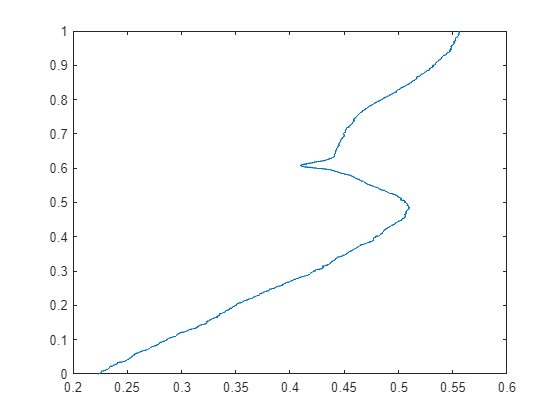

% getting F1 score average for all images
% write file to txt: https://uk.mathworks.com/matlabcentral/answers/111326-how-i-can-write-value-of-variable-in-text-file
% https://uk.mathworks.com/help/matlab/ref/fprintf.html
%https://uk.mathworks.com/matlabcentral/answers/833188-how-to-save-data-in-txt-format-without-scientific-notation

total_score = 0;

sens_vals = 0:0.001:1;
test_score = zeros(1, length(sens_vals));
sens_used = zeros(1, length(sens_vals));

for i = sens_vals
    for j = 1:12
        ImDir='Images/';

        %load image 
        imFile=[ImDir,'im',int2str(j),'.jpg'];
        I=im2double(imread(imFile));
        
        %segment image
        segPred=segment_image(I, i); %<<<<<< calls your method for image segmentation
        
        %convert segmentation to a boundary map, if necessary
        segPred=round(segPred);
        inseg=unique(segPred(:));
        if min(inseg)==0 & max(inseg)==1
            %result is a boundary map
            boundariesPred=double(segPred);
        else
            %result is a segmentation map
            boundariesPred=double(convert_seg_to_boundaries(segPred)); %convert segmentation map to boundary map
        end
            
        %load human segmentations
        humanFiles=[ImDir,'im',int2str(j),'seg*.png'];
        numFiles=length(dir(humanFiles));
        for k=1:numFiles
            humanFile=['Images/im',int2str(j),'seg',int2str(k),'.png'];
            boundariesHuman(:,:,k)=im2double(imread(humanFile));
        end
        
        %evaluate and display results
        [f1score,TP,FP,FN]=evaluate(boundariesPred,boundariesHuman);

        total_score = total_score + f1score;
    end

    test_score(uint16(i*1000 + 1)) = total_score/12;
    sens_used(uint16(i*1000 + 1)) = i;
    total_score = 0;
end

plot(test_score, sens_used, 'b--o'); title('Sens to Score Ratio'); xlabel('Score'); ylabel('Sensitivity');


[val_max_score, idx_max_score] = max(test_score);
best_sens = sens_used(idx_max_score)

best_sens = 1


fileID = fopen('best_sens_value.txt','w');
fprintf(fileID,'%.3f \n', best_sense);
fclose(fileID);

Error using fprintf
Invalid format.